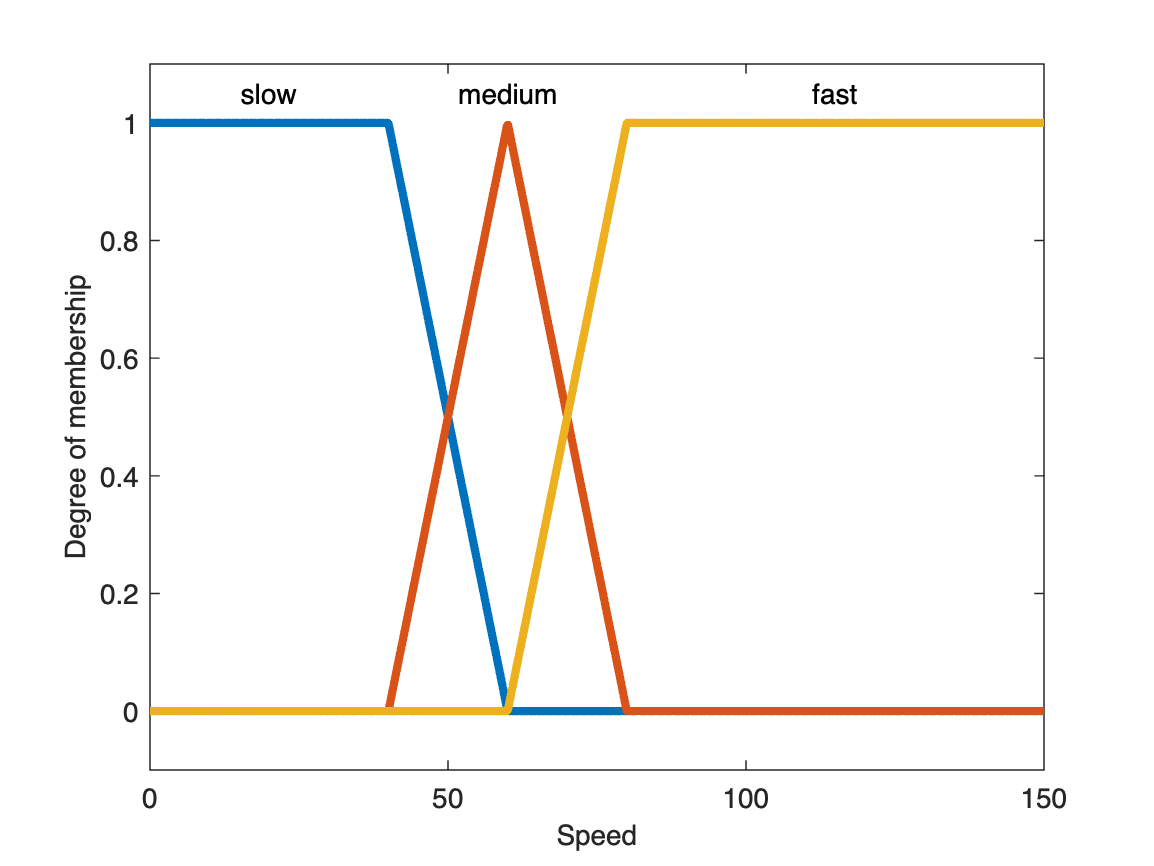

% SIT215 PBL-1 Fuzzy Logic
% Speed(KM), Distance(M), ?Weight(KG)
% We need 2D or possible 3D for more accurate result.

% Create FIS
fuzzyFIS = mamfis(...
    'Name', 'Uses Binary MFs',...
    'NumInputs', 1, 'NumInputMFs', 3, ...
    'NumOutputs', 1, 'NumOutputMFs', 3, ...
    'AddRule', 'none' ...
    );

% Update Input
fuzzyFIS.Inputs(1).Name = 'Speed';
fuzzyFIS.Inputs(1).Range = [0 150];
fuzzyFIS.Inputs(1).MembershipFunctions(1).Name = 'slow';
fuzzyFIS.Inputs(1).MembershipFunctions(1).Type = 'trapmf';
fuzzyFIS.Inputs(1).MembershipFunctions(1).Parameters = [0 0 40 60];
fuzzyFIS.Inputs(1).MembershipFunctions(2).Name = 'medium';
fuzzyFIS.Inputs(1).MembershipFunctions(2).Type = 'trapmf';
fuzzyFIS.Inputs(1).MembershipFunctions(2).Parameters = [40 60 60 80];
fuzzyFIS.Inputs(1).MembershipFunctions(3).Name = 'fast';
fuzzyFIS.Inputs(1).MembershipFunctions(3).Type = 'trapmf';
fuzzyFIS.Inputs(1).MembershipFunctions(3).Parameters = [60 80 150 200];

% Plot Input MFs
plotmf(fuzzyFIS, 'input', 1, 1000);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);

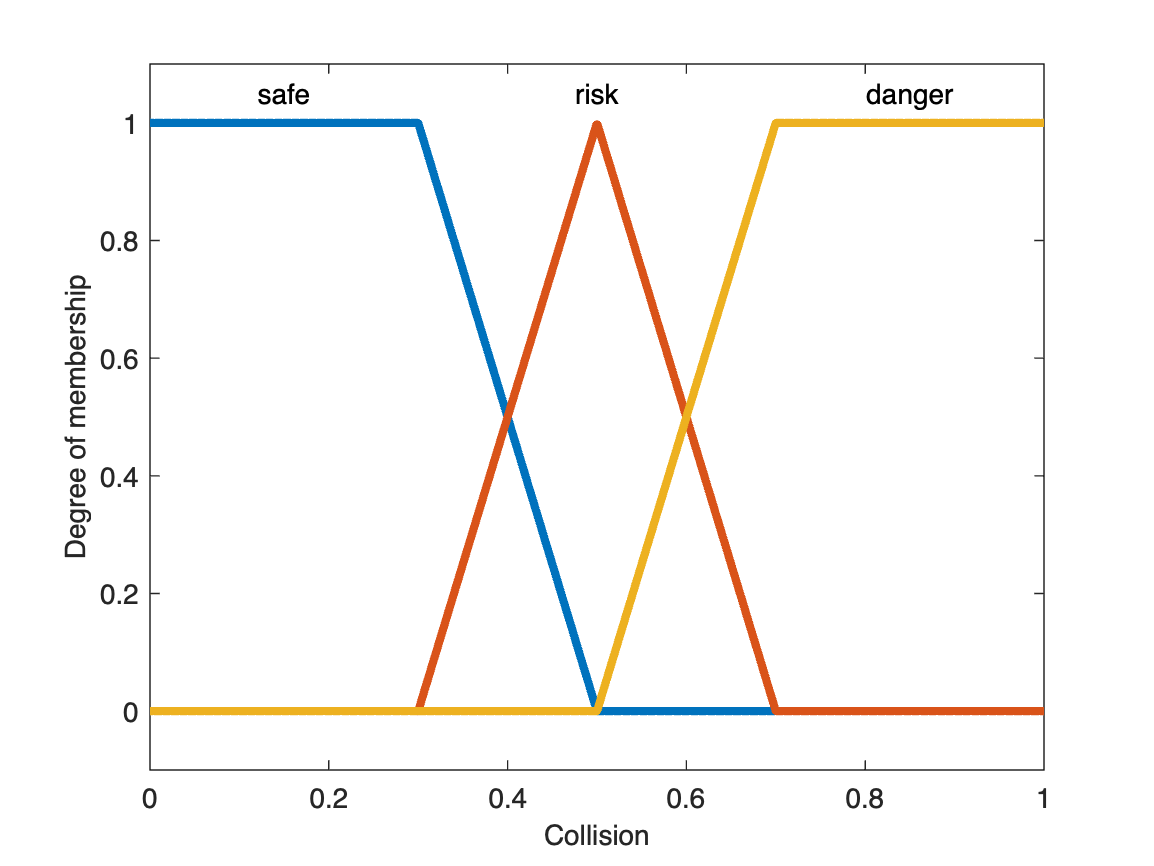

% Update Output
fuzzyFIS.Outputs(1).Name = 'Collision';
fuzzyFIS.Outputs(1).MembershipFunctions(1).Name = 'safe';
fuzzyFIS.Outputs(1).MembershipFunctions(1).Type = 'trapmf';
fuzzyFIS.Outputs(1).MembershipFunctions(1).Parameters = [0 0 0.3 0.5];
fuzzyFIS.Outputs(1).MembershipFunctions(2).Name = 'risk';
fuzzyFIS.Outputs(1).MembershipFunctions(2).Type = 'trapmf';
fuzzyFIS.Outputs(1).MembershipFunctions(2).Parameters = [0.3 0.5 0.5 0.7];
fuzzyFIS.Outputs(1).MembershipFunctions(3).Name = 'danger';
fuzzyFIS.Outputs(1).MembershipFunctions(3).Type = 'trapmf';
fuzzyFIS.Outputs(1).MembershipFunctions(3).Parameters = [0.5 0.7 1 1];

% Plot Output MFs
plotmf(fuzzyFIS, 'output', 1, 1000)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);

% Specify Rules
rules = [...
    "If Speed is slow then Collision is safe"; ...
    "If Speed is medium then Collision is risk"; ...
    "If Speed is fast then Collision is danger" ...
    ]

rules = 3×1 string array
    "If Speed is slow then Collision is safe"
    "If Speed is medium then Collision is risk"
    "If Speed is fast then Collision is danger"


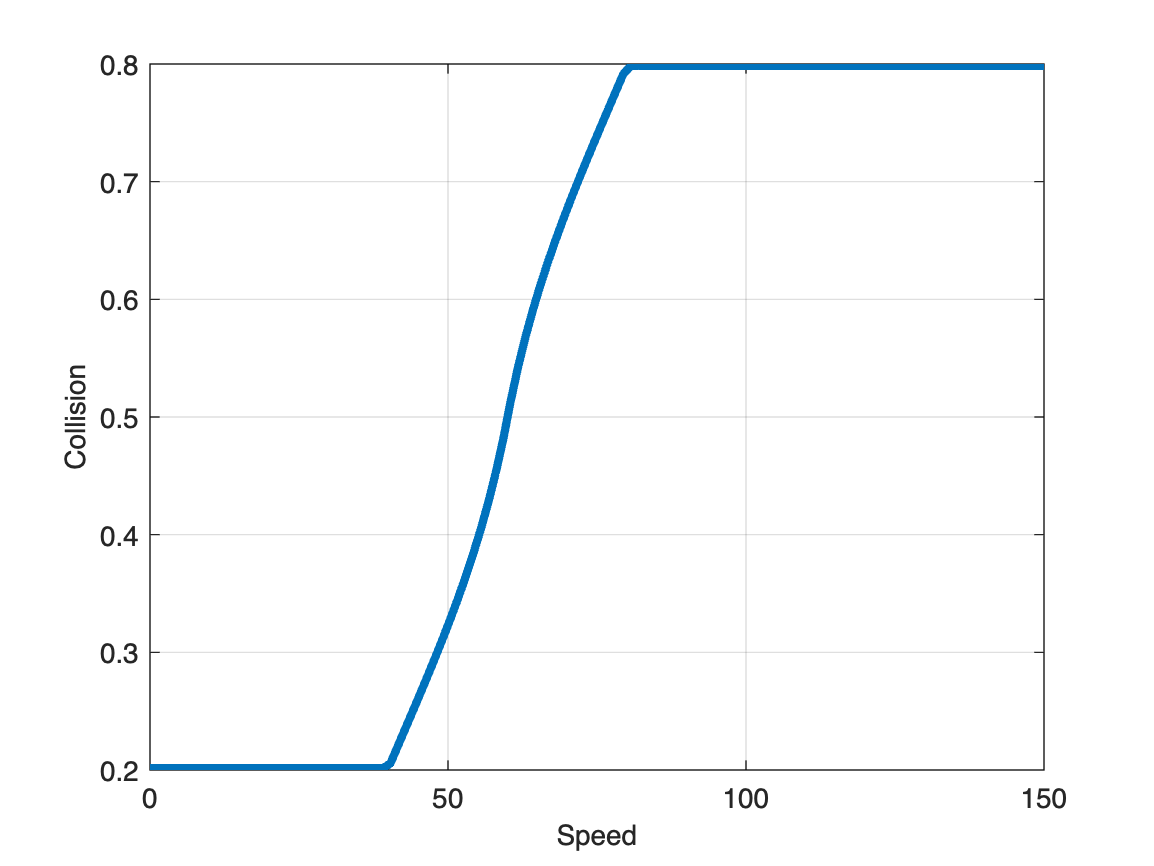


fuzzyFIS = addRule(fuzzyFIS, rules);

% Show control surface
options = gensurfOptions;
options.NumGridPoints = 120;

gensurf(fuzzyFIS, options);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on